%% Find all subfolders
parentFolder = 'C:\Users\Alyssa\Documents\QuadStateEstimator\Tests\RobMech\Dynamic\TestSeries_3\';
allSubFolders = genpath(parentFolder);
% Parse into a cell array.
remain = allSubFolders;
listOfFolderNames = {};
while true
	[singleSubFolder, remain] = strtok(remain, ';');
	if isempty(singleSubFolder)
		break;
    end
    if ~contains(singleSubFolder, 'arb') && ~contains(singleSubFolder, 'calib') && ~contains(singleSubFolder, 'sim')
	    listOfFolderNames = [listOfFolderNames singleSubFolder];
    end
end
numberOfSubFolders = length(listOfFolderNames);

%currentFolder = fullfile('C:\Users\Alyssa\Documents\QuadStateEstimator\QuadSimEnv\Results\Traj-0026');
%currentFolder = fullfile('C:\Users\Alyssa\Documents\QuadStateEstimator\Tests\RobMech\Dynamic\TestSeries_3\arb_3\sim_16Hz');
currentFolder = fullfile('C:\Users\Alyssa\Documents\QuadStateEstimator\QuadSimEnv\Results\Traj-0027');
% for l=2:numberOfSubFolders
 % currentFolder = string(listOfFolderNames(l));
   

[imgSet, imuSet, gtSet, hybrid, px4Set] = applySettings('px4');
importGT = true;
rerunP3P = false;

% Defaults
refTime = datetime(2000, 01, 01); %if importing simulation data
imgLogFolder = currentFolder;
p3pLogFolder = currentFolder;
simLogFolder = currentFolder;
px4ImuLogFolder = currentFolder;
mocapLogFolder = currentFolder;
saveFolder = currentFolder;

% 
% % SET OPTIONS
% importSimLogs =true;
% importRealImu = false;
% importRealImages = false;
% importImages = true;
% importMocap =false;
% hybrid = false;
% rtRounding = 10;

%What options are there?

% imgSet, imuSet, gtSet, hybrid
% importGT
% rerunP3P

%

%For importing real data:
imuFileName = '\imuReadings_sync.mat'

imuFileName = '\imuReadings_sync.mat'

mocapFileName = '\mocapLog_sync.mat'

mocapFileName = '\mocapLog_sync.mat'

simoutFileName = '\simout.mat';

if hybrid == true %Current folder is true data folder
    %%Fix folder references
    simFolderName = 'sim_16Hz';
    %Override folders:
    if imgSet == 0
        imgLogFolder = fullfile(currentFolder, '\', simFolderName);
        p3pLogFolder = imgLogFolder;
    end
    if imuSet == 0 || gtSet == 0
        simLogFolder = fullfile(currentFolder, '\', simFolderName);
    end

    %%Fix reference time
    temp = load(px4ImuLogFolder);
    refTime = datetime(temp.timestamps_imu(1), 'Format', 'yyyyMMdd_HHmmss_SSS');
end

if px4Set == 1
    px4LogFolder = 'C:\Users\Alyssa\Documents\QGroundControl\Logs\testLog_2025-7-21-19-25';
    files_in_px4_folder = dir(px4LogFolder);
    ind = contains({files_in_px4_folder.name}, 'estimator_states_0');
    px4EkfLogFolder = strcat(px4LogFolder,'\', files_in_px4_folder(ind).name);
    ind = contains({files_in_px4_folder.name}, 'sensor_combined_0');
    px4ImuLogFolder = strcat(px4LogFolder, '\', files_in_px4_folder(ind).name);
end
% %File directories
% %imgFolder = fullfile('.', '/QuadSimEnv/Results/Traj-0024');
% 
% imgFolder = fullfile(currentFolder);
% logFile = fullfile(currentFolder, 'simout.mat');
% saveFolder = fullfile(currentFolder);
% imuLogFolder = fullfile(currentFolder, '\imuReadings_sync.mat');
% mocapLogFolder =fullfile(currentFolder, '\mocapLog_sync.mat');
% p3pFolder = fullfile(currentFolder);
% 




% INITIALISE CONSTANTS
clear imu p3pResult ekfResult groundTruth imageStream

global g;
if px4Set == 1
    g = [0; 0; -9.80665];
else
    g = [0; 0; -9.81];
end

%INITIALISE WORLD MAP
map = load('./Resources/map.mat');

%Camera variables
%K = [1274.58238813250 0 627.693937913345; 0 1273.36371905619 405.441250468717; 0 0 1]; %23 mm calibration
%K=   [302.9345 0 161.3325; 0 310.8146 131.1024; 0 0 1.0000]; %31 mm calib, esp32 
K = [458.8803 0 235.5162; 0 458.9989 167.8936; 0 0 1];%esp32 svga
%K = [1107 0 960; 0 1107 540; 0 0 1]; %virtual camera

%Checkerboard variables
X_pnts_W = map.worldObjectStruct.checkers.Corners/1000; %in m
checkerSize = map.worldObjectStruct.checkers.NumSquares;
checkerEdgeLength = map.worldObjectStruct.checkers.SquareSize; %mm
checker_w_mm = 31*checkerSize(2);
checker_h_mm = 31*checkerSize(1);

%Known coordinate transformations (mapping)
Rt_uw2rw  = map.worldObjectStruct.transforms.rt_sim2world;
Rt_imu2rq = map.worldObjectStruct.transforms.rt_imu2genquad;
Rt_rc2rq = map.worldObjectStruct.transforms.rt_gencam2genquad;
%R_align = eul2rotm(deg2rad([8 1.5 0.5]), 'XYZ'); %eyeball
R_align = eye(3);

%other variables
p3pResult = struct();
inlierThreshold =1;


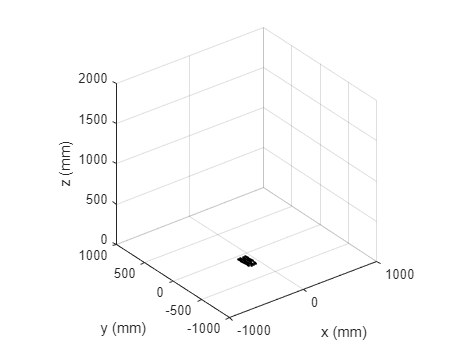

%INTIALISE PLOT
close all

%ADD TRAJECTORIES
plotStruct = initPlots('KneipN', 'Verification', 'EKF');
p3pPlotting.addCheckerboard(plotStruct.traj.Ax, X_pnts_W);

%IMPORT & PLOT LOGGED DATA

%% IMPORT IMU DATA
imu.rawdata = createArray(6,0, 'double');
imu.time = createArray(1, 0, 'datetime');
imu.time = datetime(imu.time, 'Format', 'yyyyMMdd_HHmmss_SSS');
if px4Set == 1
    imuLog = readtable(px4ImuLogFolder);
    imu.rawdata = [table2array(imuLog(:, 2:4)), table2array(imuLog(:, 7:9))]';
    time_temp = seconds(table2array(imuLog(:, 1)) * 10e-7)';
    %refTime = datetime(time_temp(1,1), 'Format', 'yyyyMMdd_HHmmss_SSS');
    imu.time = datetime(refTime+time_temp, 'Format', 'yyyyMMdd_HHmmss_SSSSSS')
elseif imuSet ==1
    imuLog = load(fullfile(px4ImuLogFolder, imuFileName));
    imu.time = datetime(imuLog.timestamps_imu', 'InputFormat', 'yyyyMMdd_HHmmss_SSS'); 
    imu.rawdata = imuLog.imuMsgLog';  
    imu.calibdata = createArray(6,size(imu.time, 2), 'double');
elseif imuSet ==0 
    [imu.rawdata, imu.time] = importSimLog_imu(fullfile(simLogFolder, simoutFileName), refTime);
end

imu = struct with fields:
    rawdata: [6×3520 double]
       time: [20000101_000000_900825    20000101_000001_114096    20000101_000001_118601    20000101_000001_123107    20000101_000001_127661    20000101_000001_132120    20000101_000001_136625    20000101_000001_141130    …    ] (1×3520 datetime)




%% Calibrate IMU
%Also calibration?
if px4Set == 0
    ba_stat =[-0.1550; 0.0886; -0.0226];
    bg_stat = [0.0016; 0.0028; 0.0015];
    %Set calibration parameters
    ba_calib = [-0.173; -0.164; 0.329]+ ba_stat;
    Ka_calib = [0.992 0 0; 0 0.989 0; 0 0 0.975];
    %bg_calib = [0.009; -0.038; -0.006];
    bg_calib = [0 0 0]' +bg_stat;
    Kg_calib = [1 0 0; 0 1 0; 0 0 1];
    R_imu2rq = eul2rotm(deg2rad([-0.431, -1.874, 0]), 'XYZ');
% elseif px4Set == 1 %DELETED BECAUSE SENSOR_COMBINED IS CALIBRATED
%     %Set calibration parameters
%     ba_calib = [-0.171486377716064453; -0.222010612487792969; 0.320221424102783203];
%     Ka_calib = [0.992233514785766602 0 0; 0 0.988944113254547119 0; 0 0 0.975104629993438721];
%     %bg_calib = [0.009; -0.038; -0.006];
%     bg_calib = [0 0 0]';
%     Kg_calib = [1 0 0; 0 1 0; 0 0 1];

    Rt_imu2rq(1:3, 1:3) = R_imu2rq;   
    for r=1:size(imu.time, 2)
        imu.calibdata(:,r) = [Kg_calib * (imu.rawdata(1:3, r) - bg_calib); Ka_calib * (imu.rawdata(4:6, r)-ba_calib)];
    end
end

%% Import ground truth
if importGT == true
%if (importSimLogs == true) || (importMocap == true) || (importRealImu == true)

    %Create struct to hold verification data
    groundTruth.quadState = [];
    groundTruth.quadRt = createArray(3,4, 0, 'double');
    groundTruth.quadTime = createArray(1, 0, 'datetime');
    groundTruth.quadTime = datetime(groundTruth.quadTime, 'Format', 'yyyyMMdd_HHmmss_SSS');
    groundTruth.camPose = createArray(7,0, 'double');
    groundTruth.camTime = createArray(1, 0, 'datetime');
    groundTruth.camTime = datetime(groundTruth.camTime, 'Format', 'yyyyMMdd_HHmmss_SSS');
    groundTruth.elapsedTime_synced = createArray(1,0, 'double');

    if px4Set ==1
        px4EkfLog = readtable(px4EkfLogFolder);
        time_temp = seconds(table2array(px4EkfLog(:, 2)) * 10e-7)';
        groundTruth.quadTime = datetime(refTime+time_temp, 'Format', 'yyyyMMdd_HHmmss_SSSSSS');
        groundTruth.quadState = [table2array(px4EkfLog(:, 10:12)), table2array(px4EkfLog(:, 3:9))]'; %exclude biases, as they are in another space
        for r=1:size(groundTruth.quadState, 2)
            %Convert to NED
            q_ned2nwu = eul2quat([pi 0 0], 'XYZ');
            R_ned2nwu = quat2rotm(q_ned2nwu);
            groundTruth.quadState(4:7, r) = quatmultiply(q_ned2nwu, groundTruth.quadState(4:7, r)')'; %quaternion
            groundTruth.quadState(1:3, r) = R_ned2nwu * groundTruth.quadState(1:3, r); %position
            groundTruth.quadState(8:10, r) = R_ned2nwu * groundTruth.quadState(8:10, r); %velocity
            groundTruth.quadRt(1:3,1:3,r) = quat2rotm(groundTruth.quadState(4:7, r)');
            groundTruth.quadRt(1:3,4,r) = groundTruth.quadState(1:3, r)';
        end
    elseif gtSet == 1 %If import real ground truth data (Mocap)
    %%%IMPORT MOCAP
        Rt_mc2rw = map.worldObjectStruct.transforms.rt_mocap2world;
        Rt_mcq2rq = map.worldObjectStruct.transforms.rt_mcquad2genquad;
        Rt_mcq2rq(1:3, 1:3) = Rt_mcq2rq(1:3, 1:3)*R_align;  
        [groundTruth.quadRt, groundTruth.quadState, groundTruth.quadTime] = importMocapLog(fullfile(mocapLogFolder, mocapFileName),  Rt_mc2rw, Rt_mcq2rq);
    elseif gtSet == 0
        [groundTruth.quadRt, groundTruth.quadTime, groundTruth.quadState] = importSimLog_gt(fullfile(simLogFolder, simoutFileName), refTime);
    end

    %%synchronise ground truth and imu data
    startTime_imu = imu.time(1);
    endTime_imu = milliseconds(imu.time(end)-startTime_imu)/1000;
    for t=1:size(groundTruth.quadTime,2)
        groundTruth.elapsedTime_synced(1,t)=milliseconds(groundTruth.quadTime(1,t)-startTime_imu)/1000;
    end
    %get closest times
    [closestDiff, closestIndex] = min(abs(groundTruth.elapsedTime_synced));
    syncedTime_zeroIndex_gt = closestIndex;
    [closestDiff, closestIndex] = min(abs(groundTruth.elapsedTime_synced(1,:)-endTime_imu));
    syncedTime_endIndex_gt = closestIndex;
end

## Plot ground truth

if importGT == true
    %update plots
    %lineObj_Ver = plotStruct.traj.plotLines.Verification.line;
    %axTextArr_Ver=plotStruct.traj.plotLines.Verification.frameText;
    %axLineArr_Ver = plotStruct.traj.plotLines.Verification.frameLines;
    plotStruct.traj.plotLines.Verification = p3pPlotting.updateTraj(plotStruct.traj.plotLines.Verification, groundTruth.quadState);
end

% %Import images for P3P  
if imgSet == 1
    if rerunP3P == true
        imageStream = struct();
        imageStream.img = [];
        imageStream.time = createArray(1, 0, 'datetime');
        imageStream.time = datetime(imageStream.time, 'Format', 'yyyyMMdd_HHmmss_SSS');
        [imageStream.img, imageStream.time] = imgFuncs.importImageSeq(imgLogFolder, imgSet, refTime);
        imageStream.res = size(imageStream.img(:,:,1));
    end
    
    %RUN AND PLOT P3P FOR EACH CHECKERBOARD IMAGE
    if rerunP3P == true
        goodFrameCounter = 0;
        totalFrames = size(imageStream.time,2);
        imageSize = imageStream.res;
        for i=1:totalFrames
            disp(strcat("Working on frame ", string(i)));
            %Get current frame
            I=imageStream.img(:,:,i);
            %Find checkerboard corners
            [x_pnts_i, checkerSize_detected] = detectCheckerboardPoints(I);
            x_pnts_i = transpose(x_pnts_i);    
            %discard any frames where too few corners have been detected
            if (checkerSize_detected(1) ~= checkerSize(1)) || (checkerSize_detected(2) ~= checkerSize(2))
                disp(strcat("Discarding frame ", string(i)));
                continue
            end
            %Otherwise, continue:
            goodFrameCounter = goodFrameCounter +1;
            if goodFrameCounter == 1
                startIndex = 1;
            end
            % Run P3P
            p3pResult = runP3P(p3pResult, imageStream.time(i), x_pnts_i, X_pnts_W, K, Rt_rc2rq, imageSize, checkerSize, inlierThreshold,  'KneipN');
            %plotStruct.traj.plotLines.KneipN = p3pPlotting.updateTraj(plotStruct.traj.plotLines.KneipN, groundTruth.quadState);
            %drawnow
            % %Display checkerboard image for this iteration - for troubleshooting
            % if (checkerSize_detected(1) <= checkerSize(1)) || (checkerSize_detected(2) <= checkerSize(1)) 
            %     if i==1
            %         checkerFig = figure();
            %         checkerAx = axes('Parent', checkerFig);
            %         checkerImg = imshow(imgFuncs.markDetectedCheckers(I, x_pnts_i), 'Parent', checkerAx);
            %     else
            %         checkerImg.CData = (imgFuncs.markDetectedCheckers(I, x_pnts_i));
            %         drawnow;
            %     end 
            % end
         end
    
    %     Calculate errors?
        if importGT == true
            for i=1:size(p3pResult.KneipN.time, 2)
                %Find the closest ground truth measurement for this time
                [closestDiff, closestIndex] = min(abs(groundTruth.quadTime(1,:)-p3pResult.KneipN.time(1, i)));
                closestGT = groundTruth.quadState(:,closestIndex);
                for n=1:size(p3pResult.KneipN.quadPoseArr,2)
                    [p3pResult.KneipN.quadPoseError(1, n, i), p3pResult.KneipN.quadPoseError(2, n, i)] = getPoseError(closestGT, p3pResult.KneipN.quadPoseArr(:,n,i));
                end
                [pose, err, ind] = chooseMinPoseErr(p3pResult.KneipN.quadPoseArr(:,:,i), closestGT, 1, 1);
                if ~isnan(err)
                    p3pResult.KneipN.best.quadPose(:,i) = pose;
                    p3pResult.KneipN.best.err(:,i) = err;
                    p3pResult.KneipN.best.truePose(:,i) = closestGT;
                    [p3pResult.KneipN.best.quadPose(:,i), p3pResult.KneipN.best.err(:,i), bestIndex] = chooseMinPoseErr(p3pResult.KneipN.quadPoseArr(:,:,i), closestGT, 1, 1);
                end
                %plotStruct.traj = updatePlot(plotStruct.traj, p3pResult.KneipN.best.quadPose);
                %drawnow
                plotStruct.traj.plotLines.KneipN = p3pPlotting.updateTraj(plotStruct.traj.plotLines.KneipN, p3pResult.KneipN.best.quadPose);
                drawnow
            end
        end
    
       % p3pResultFile = fullfile('.', '/Results/p3pResult.mat')
        save(fullfile(p3pLogFolder,  '/p3pResult.mat'), 'p3pResult'); 
    end 
    % end
end

## run 3D state estimator

 
%g = [0; 0; -9.79];
startCalc = 6; %Which log values to start at
endCalc =size(imu.time,2);

%Known coordinate transformations (mapping)
Rt_uw2rw = map.worldObjectStruct.transforms.rt_sim2world;
Rt_imu2rq = map.worldObjectStruct.transforms.rt_imu2genquad;
Rt_rc2rq = map.worldObjectStruct.transforms.rt_gencam2genquad;

%Import measurement history 
%p3pResultFile = fullfile(currentFolder, '/sim_16Hz', '/p3pResult.mat');
if imgSet == 1
    p3pResultLoad = load(fullfile(p3pLogFolder, '/p3pResult.mat'));
    p3pData = p3pResultLoad.p3pResult.KneipN;
    z_timeHist = datetime(p3pData.time, 'Format', 'yyyyMMdd_HHmmss_SSS');
else
    z_timeHist = [];
end
%Get control input history
u_hist = imu.rawdata;
%u_hist = imu.rawdata;
u_timeHist = imu.time;

%% INITIALISE STATE AND ESTIMATOR VARIABLES
if importGT ==true
    x_k = [groundTruth.quadState(1:7,syncedTime_zeroIndex_gt); [0; 0; 0]]; %consider initialising from known position
else
    x_k = [0; 0; 0.32; 0; 1; 0; 0; 0;  0; 0]; %otherwise, initial guess
end
% if px4Set ==1
%     x_k = [0; 0; 0; 0; 1; 0; 0; 0;  0; 0]; %temporary measure - PX4 is in NED, so don't grab it's first guess!
% end
%Why using second value? There's something wrong with the first. probably due to derivatives in model)

%**** 10 elements ************
% %Initialise state - 10 el
x_k = x_k;
[ekfResult, P_k, Q, W, t_delta] = EKF_3dQuad_10el_funcs.initEKF(imu.time(1,startCalc), x_k);

%***************************


%**** 16 elements *****

% % %Initialise state - 16 el
% x_k = [x_k; [0; 0; 0]; [0; 0; 0]];
% [ekfResult, P_k, Q, W, t_delta] = EKF_3dQuad_16el_funcs.initEKF(imu.time(1,startCalc), x_k);

%***************************

% if importSimLogs == true
%     t_delta = milliseconds((u_timeHist(1,2) - u_timeHist(1,1)))/1000; %override t_delta for sim
% end

oldIndex = 0;
count = 1;
t_k = datetime(u_timeHist(1,startCalc), 'Format', 'yyyyMMdd_HHmmss_SSSSSS'); %first time
startTime_imu = ekfResult.time(1,1);
lastCorrectionTime = startTime_imu;

for i=startCalc:endCalc-1%size(u_hist,2)
   
    t_k = datetime(u_timeHist(1,i), 'Format', 'yyyyMMdd_HHmmss_SSSSSS'); %current time
    t_next = datetime(u_timeHist(1,i+1), 'Format', 'yyyyMMdd_HHmmss_SSSSSS'); %next time
    u_k = u_hist(:, i); %current control input
    t_delta = milliseconds(t_next-t_k)/1000;
    
    %check if there is a measurement for this time
    z_k = NaN; %assume no measurement
    timeSinceLastCorrection = milliseconds(t_k-lastCorrectionTime)/1000;   
    if imgSet == 1
        [closestDiff, closestIndex] = min(abs(z_timeHist(1,:)-t_k)); %find index of closest time
        if (((milliseconds(closestDiff)/1000) <= (t_delta)) && (z_timeHist(1, closestIndex) <= t_k) && closestIndex>oldIndex)%if it is close enough, and not ahead
            %if not too much time has passed
            if timeSinceLastCorrection < 0.3
                %Choose soln closest to previous estimate
                p3pSolns = reshape(p3pData.quadPoseArr(:,:,closestIndex), 7,[]);
                [z_k,a,b] = chooseMinPoseErr(p3pSolns, x_k, 1.2, 2);
            else %if too much time has passed
                % Or choose min reproj
                temp=p3pFuncs.transformPose(p3pData.mostInliers.Rt(:,:,closestIndex), p3pFuncs.invertRt(Rt_rc2rq));
                z_k = [temp(1:3, 4); rotm2quat(temp(1:3, 1:3))'];
            end
            oldIndex = closestIndex; %update index
            lastCorrectionTime = z_timeHist(1, closestIndex);
        end
    end


    %run EKF to find next state
    [x_k, P_k, proTerm_k, xHat_k, zHat_k, z_out_k] = EKF_3dQuad_10el_funcs.EKF_loop(g, x_k, P_k, u_k, Q, z_k, W, t_delta, Rt_imu2rq, Rt_rc2rq, count);
       
    ekfResult.time(:,count+1) = (t_k+seconds(t_delta));
    ekfResult.stateEst(:,count+1) = x_k;
    ekfResult.processTerm(:,count+1) = proTerm_k;
    ekfResult.statePred(:,count+1) = xHat_k;
    ekfResult.measPred(:,count+1) = zHat_k;
    ekfResult.P(:,:,count+1) = P_k;
    ekfResult.input(:,count+1) = u_k;
    ekfResult.rt(:,:,count+1)= [quat2rotm(transpose(x_k(4:7, 1))), (x_k(1:3,1))];     %RECREATE RT matrix for plotting
    ekfResult.elapsedTime(1,count+1) = milliseconds(t_k - startTime_imu)/1000;
    ekfResult.timeSinceLastCorrection(1, count+1) = timeSinceLastCorrection;
    %rtHist_ekf(:,1:3,i+1)= (quat2rotm(transpose(x_k(4:7, 1))));
    % Record z_hist
    if ~isnan(z_k)
       ekfResult.z(:,count+1) = z_out_k;
       ekfResult.zHist(:, end+1) = [ekfResult.elapsedTime(1,count+1); z_out_k];
       ekfResult.zInHist(:, end+1) = [ekfResult.elapsedTime(1,count+1); z_k];
    else
       ekfResult.z(:,count+1) = NaN(7,1);
    end
    
    count = count + 1;

    plotStruct.traj.plotLines.EKF=p3pPlotting.updateTraj(plotStruct.traj.plotLines.EKF, ekfResult.stateEst(:,1:end));
    drawnow;
end


%plotStruct.traj.plotLines.EKF.Data = ekfResult.rt(:,:,1:2);
%p3pPlotting.updateTraj(plotStruct.traj.plotLines.EKF.line, plotStruct.traj.plotLines.EKF.frameText, plotStruct.traj.plotLines.EKF.frameLines, ekfResult.rt(:,:,startCalc:end))
drawnow


## Calculate errors

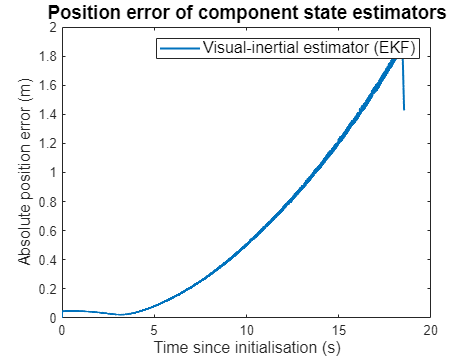

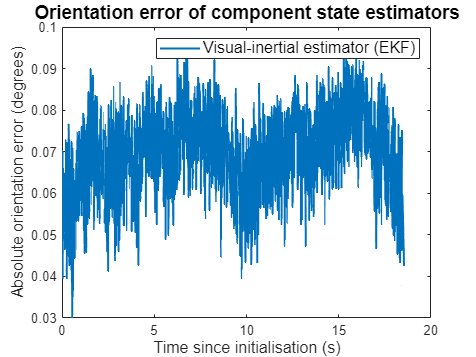


%Calculate EKF error
if importGT == true

    for i=1:size(ekfResult.stateEst, 2)
        %Find the closest ground truth measurement for this time
        [closestDiff, closestIndex] = min(abs(groundTruth.quadTime(1,:)-ekfResult.time(1, i)));
        %calculate the pose error
        [ekfResult.error(1, i),ekfResult.error(2, i)] = getPoseError(groundTruth.quadState(:, closestIndex), ekfResult.stateEst(:, i));
        ekfResult.truePose(:,i) = groundTruth.quadState(:, closestIndex);
    end
    
    %Calculate P3P error
    ekfP3pErrArr = createArray(3,0, 'double');
    for i=1:size(ekfResult.z, 2)
        if ~isnan(ekfResult.z(1, i))
            %Find the closest ground truth measurement for this time
            [closestDiff, closestIndex] = min(abs(groundTruth.quadTime(1,:)-ekfResult.time(1,i)));
            % state_GT = quad_stateHist_GT(:, closestIndex);
            % state_P3P = [z_hist(2:4, i);
            %              quatmultiply(z_hist(5:8,i)', rotm2quat(R_rc2rq'))']; 
            % errArr_P3P(1, i) = z_hist(1, i);
            [ekfResult.zError(1, i), ekfResult.zError(2, i)] = getPoseError(groundTruth.quadState(:,closestIndex), ekfResult.z(:,i));
            ekfP3pErrArr(:,end+1) = [ekfResult.elapsedTime(1,i); ekfResult.zError(1, i); ekfResult.zError(2, i)];
        else
            ekfResult.zError(1:2, i) = NaN(2,1);
        end
    end

    %% SAVE EKF RESULT
    basename = '\ekfResult_16el_trap_deadreckon';
    save(fullfile(saveFolder, strcat(basename, '.mat')), 'ekfResult');


    %% PLOT ERRORS
    
    cmap = parula(4);

    %%Plot them
    %Position error
    errPlot_pos = figure();
    errAx_pos = axes('Parent', errPlot_pos);
    plot(errAx_pos, ekfResult.elapsedTime(1,:), ekfResult.error(1,:), 'LineWidth',1.5);
    hold on;
    plot(errAx_pos, ekfP3pErrArr(1,:), ekfP3pErrArr(2,:), '--', 'LineWidth', 2);
    title('Position error (m)');
    title('Position error of component state estimators', 'FontSize', 14);
    legend('Visual-inertial estimator (EKF)', 'Visual estimator (P3P)', 'FontSize', 12);
    xlabel('Time since initialisation (s)', 'FontSize', 12);
    ylabel('Absolute position error (m)', 'FontSize', 12);
    hold off;

    f = gcf;
    name = strcat(basename, '_posErr');
    exportgraphics(f, fullfile(saveFolder, strcat(name, '.emf')));
    savefig(f, fullfile(saveFolder,  strcat(name, '.fig')));
    
    %Angular error
    errPlot_ang = figure();
    errAx_ang = axes('Parent', errPlot_ang);
    % Plot EKF error
    plot(errAx_ang, ekfResult.elapsedTime(1,:), ekfResult.error(2,:), 'LineWidth', 1.5);
    hold on
    % Plot P3P error
    plot(errAx_ang, ekfP3pErrArr(1,:), ekfP3pErrArr(3,:), '--', 'LineWidth', 2);
    title('Orientation error of component state estimators', 'FontSize', 14);
    legend('Visual-inertial estimator (EKF)', 'Visual estimator (P3P)', 'FontSize', 12);
    xlabel('Time since initialisation (s)', 'FontSize', 12);
    ylabel('Absolute orientation error (degrees)', 'FontSize', 12);
    
    hold off;
    
    f = gcf;
    name = strcat(basename, '_orientErr');
    exportgraphics(f, fullfile(saveFolder, strcat(name, '.emf')));
    savefig(f, fullfile(saveFolder,  strcat(name, '.fig')));



end 

## Plot state development

## Convert quaternions to euler angles --> more meaningful

%EKF estimates
numLoops = size(ekfResult.time, 2);
orientCov_eul = zeros(3,3,numLoops);
orient_EKF_eul = zeros(3,numLoops);
for t=1:numLoops

    %convert quaternion estimate to euler
    orient_EKF_eul(:,t) = rad2deg(quat2eul(ekfResult.stateEst(4:7, t)', 'XYZ'))'; %convert quaternion to euler
    q = ekfResult.stateEst(4:7, t);

    %propagate covariance
    orientCov_quat = ekfResult.P(4:7, 4:7, t);
    jacob = jacobianEultoQuat(q);
    orientCov_eul(:,:,t) = rad2deg(jacob * orientCov_quat * jacob');

end

%P3P estimates
if importImages == true
    numP3P = size(ekfResult.zHist,2);
    orient_P3P_eul = zeros(3,numP3P);
    for t=1:numP3P
        %convert quaternion estimate to euler
        orient_P3P_eul(:,t) = rad2deg(quat2eul(ekfResult.zHist(5:8, t)', 'XYZ'))'; %convert quaternion to euler
    end
end

Unrecognized function or variable 'importImages'.


%Ground truth
if importMocap ==true || importSimLogs == true
    numGT = size(groundTruth.quadTime, 2);
    orient_gt_eul = zeros(3,numGT);
    for t=1:numGT
        %convert quaternion estimate to euler
        orient_gt_eul(:,t) = rad2deg(quat2eul(groundTruth.quadState(4:7, t)', 'XYZ'))'; %convert quaternion to euler
    end
end

%Recreate state histories
stateHist_EKF_eul = [ekfResult.stateEst(1:3, :); orient_EKF_eul; ekfResult.stateEst(8:end, :)];
stateHist_P3P_eul = [ekfResult.zHist(1:3, :); orient_P3P_eul];
stateHist_gt_eul = [groundTruth.quadState(1:3,:); orient_gt_eul; groundTruth.quadState(8:end,:)];




## DO PLOTTING:

% match quternion direction in logs to estimate
if importSimLogs == true || importMocap == true
    for t=1:size(groundTruth.quadTime, 2)
        %find nearest state estimate
        [closestDiff, closestIndex] = min(abs(ekfResult.time(1,:)-groundTruth.quadTime(1,t)));
        q_comp = ekfResult.stateEst(4:7, closestIndex);
        q_gt = groundTruth.quadState(4:7, t);
        %Enforce quaternion constraints - closest quaternions
        if dot(q_comp, q_gt) < 0
            q_gt = -q_gt;
        end
        groundTruth.quadState(4:7, t) = q_gt;
    end
end

%Make plot for each state variable
numLoops = size(ekfResult.time, 2);
for i=1:size(x_k, 1)
    figure(); %create figure

    %PLOT CHANGING STATE
    x = ekfResult.elapsedTime(1,:);
    y = ekfResult.stateEst(i,:);
    plot(x, y);  
    hold on;
    
    %PLOT VARIANCE
    stateVariance = zeros(1, numLoops); %initialise array
    for t=1:numLoops
        stateVariance(1,t)=ekfResult.P(i,i,t);
    end
    stateVariance = sqrt(stateVariance);
    lowerCurve = y - abs(stateVariance);
    upperCurve = y + abs(stateVariance);
    plot(x, lowerCurve);
    hold on;
    plot(x, upperCurve);
    hold on;
    % fill(x, [y; upperCurve],[.9 .9 .9],'linestyle','none');
    % hold on;
    % 
    % fill(x, [lowerCurve; y],[.9 .9 .9],'linestyle','none');
    % hold on;
    %line(x,y)
    %errorbar(x, y, -dy, dy);
    % 
    % drawnow;
    % hold on;


    %%PLOT GROUND TRUTH
    if i <= 7
        if importSimLogs ==true || importMocap ==true
            %figure()
            x = groundTruth.elapsedTime_synced(1,syncedTime_zeroIndex_gt:end);
            y = groundTruth.quadState((i),syncedTime_zeroIndex_gt:end);
            plot(x, y);
            hold on;
        end
    end

    %plot corrections, if any (i.e., measurements in state space)
    if i<=7

        x = ekfResult.zHist(1,:);
        y = ekfResult.zHist(1+i,:);
         scatter(x,y,10, "filled");
         hold on;
        plot(x,y);
        hold on;

        %mark estimate that was corrected
        correctedEst = zeros(1, size(ekfResult.zHist, 2));
        for t=1:size(ekfResult.zHist, 2)
            t_k =  ekfResult.zHist(1, t);
            [closestDiff, closestIndex] = min(abs(ekfResult.elapsedTime(1,:)-ekfResult.zHist(1,t)));
            correctedEst(1, t) = ekfResult.stateEst(i, closestIndex);
        end
        y = correctedEst;
        %scatter(x, y, 10, "filled")
        %hold on;
        quiver(x, correctedEst, zeros(1, size(correctedEst, 2)), ((ekfResult.zHist(1+i,:)-correctedEst)), 0);
       
    end
    
    title(strcat('State variable evolution: ', string(i)));
    legend('State estimate', 'Std deviation lower bound', 'Std deviation upper bound', 'Ground truth', 'Camera estimate (correction)')

    hold off;


end;
 %end


function j = jacobianEultoQuat(q)

j_11 = -(q(3) + q(2))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  +  (q(3)-q(2)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
j_12 = (q(4)+q(1)) / ( (q(3)+q(2))^2 + (q(4)+q(1))^2 )  -  (q(4)-q(1)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
j_13 = (q(4)+q(1)) / ( (q(3)+q(2))^2 + (q(4)+q(1))^2 )  +  (q(4)-q(1)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
j_14 = -(q(3) + q(2))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  -  (q(3)-q(2)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
j_21 = 2*q(4) / (( 1 - 4*( q(2)*q(3) + q(1)*q(4) )^2 )^(1/2));
j_22 = 2*q(3) / (( 1 - 4*( q(2)*q(3) + q(1)*q(4) )^2 )^(1/2));
j_23 = 2*q(2) / (( 1 - 4*( q(2)*q(3) + q(1)*q(4) )^2 )^(1/2));
j_24 = 2*q(1) / (( 1 - 4*( q(2)*q(3) + q(1)*q(4) )^2 )^(1/2));
j_31 = -(q(3) + q(2))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  -  (q(3)-q(2)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
j_32 = (q(4) + q(1))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  +  (q(4)-q(1)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
j_33 = (q(4) + q(1))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  -  (q(4)-q(1)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
j_34 = -(q(3) + q(2))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  +  (q(3)-q(2)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );

j = [j_11 j_12 j_13 j_14;
     j_21 j_22 j_23 j_24;
     j_31 j_32 j_33 j_34];
end

function [imgSet, imuSet, gtSet, hybrid, px4Set] = applySettings(varargin)

         validSettings = {'allReal', 'allSim', 'hybrid', 'px4'};

         targetSetting = varargin{1}; %grab first argument 

         if any(strcmp(targetSetting, validSettings)) %if targetSetting is valid            
            switch targetSetting
                case validSettings{1} %all real
                    hybrid = false;
                    imgSet = 1;
                    imuSet = 1;
                    gtSet = 1; 
                    px4Set = 0;
                case validSettings{2} %all sim
                    hybrid = false;
                    imgSet = 0;
                    imuSet = 0;
                    gtSet = 0;   
                    px4Set = 0;
                case validSettings{3} %hybrid
                    hybrid = true;
                    imgSet = targetSetting(2);
                    imuSet = targetSetting(3);
                    gtSet = targetSetting(4);    
                    px4Set = 0;
                case validSettings{4} %compare to px4
                    hybrid = false;
                    imgSet = 0;
                    imuSet = 0;
                    gtSet = 1;   
                    px4Set = 1;
                end
         end
         end

         function compareOrient(quat1, t1, quat2, t2)

             eul1 = quat2eul(quat1', 'XYZ')';
             eul1 = rad2deg(unwrap(eul1, [], 2));
    
             eul2 = quat2eul(quat2', 'XYZ')';
             eul2 = rad2deg(unwrap(eul2, [], 2));

            figure();
             plot(t1, eul1')
             hold on;
             plot(t2, eul2')
         end

         %compareOrient(ekfResult.zInHist(5:8, :), ekfResult.zInHist(1, :),  mocap.quadState(4:7, :), mocap.elapsedTime(1, :))
         %compareOrient(groundTruth.quadState(4:7, :), groundTruth.elapsedTime_synced, mocap.quadState(4:7, :), mocap.elapsedTime(1, :))
         % 
          camState = reshape(out.camState_GT.signals.values, 10, []);
          compareOrient(camState(4:7, :), out.camState_GT.time',  groundTruth.quadState(4:7, :), groundTruth.elapsedTime_synced)
hold on

         camEul = rad2deg((reshape(out.camEul.signals.values, 3, [])));
        figure;
         plot(out.camEul.time', camEul(1:3, :));